# What Kind of Flower is That?

This example uses transfer learning to train a deep network that can classify images of flowers into one of 5 species.

## Download data set

You can change `pathToImages` to where you'd like to download the data set

pathToImages = "C:/work/flower_photos";

Uncomment this code to download and untar the data set

% url = "http://download.tensorflow.org/example_images/flower_photos.tgz";
% filename = fullfile(pathToImages,"flower_dataset.tgz");
% websave(filename,url);
% untar(filename,pathToImages)

## Get training and testing images

Create datastore using subfolder names

flowerds = imageDatastore(pathToImages,"IncludeSubfolders",true,"LabelSource","foldernames");

Split into randomized training and testing sets

rng default
[trainImgs,testImgs] = splitEachLabel(flowerds,0.6,"randomized");

Resize datastores

resizeTrainImgs = augmentedImageDatastore([224 224],trainImgs);
resizeTestImgs = augmentedImageDatastore([224 224],testImgs);

Determine the number of flower species

numClasses = numel(categories(flowerds.Labels));

## Create a network by modifying GoogLeNet

You could also do these steps in the Deep Network Designer.

Get the layers from GoogLeNet

net = googlenet;
lgraph = layerGraph(net);

Modify the classification and output layers

newFc = fullyConnectedLayer(numClasses,"Name","new_fc");
lgraph = replaceLayer(lgraph,"loss3-classifier",newFc);
newOut = classificationLayer("Name","new_out");
lgraph = replaceLayer(lgraph,"output",newOut);

## Set training algorithm options

Lower the learning rate for transfer learning

options = trainingOptions("sgdm","InitialLearnRate",0.001);

## Perform training

[flowernet,info] = trainNetwork(resizeTrainImgs,lgraph,options);

Training on single GPU.
Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:00 |       15.62% |       3.3324 |          0.0010 |
|       3 |          50 |       00:00:39 |       84.38% |       0.3772 |          0.0010 |
|       6 |         100 |       00:01:17 |       92.19% |       0.2534 |          0.0010 |
|       9 |         150 |       00:01:57 |       96.09% |       0.1642 |          0.0010 |
|      12 |         200 |       00:02:35 |       96.88% |       0.0896 |          0.0010 |
|      15 |         250 |       00:03:14 |       96.09% |       0.0790 |          0.0010 |
|      18 |         300 |  

## Use the trained network to classify test images

testpreds = classify(flowernet,resizeTestImgs)

testpreds = 1468×1 categorical array
     daisy 
     daisy 
     daisy 
     sunflowers 
     daisy 
     daisy 
     dandelion 
     daisy 
     daisy 
     daisy 
     daisy 
     sunflowers 
     daisy 
     daisy 
     daisy 
     dandelion 
     daisy 
     daisy 
     daisy 
     daisy 
     daisy 
     daisy 
     daisy 
     daisy 
     daisy 
     daisy 
     daisy 
     dandelion 
     tulips 
     daisy 


## Evaluate the results

Calculate the accuracy

nnz(testpreds == testImgs.Labels)/numel(testpreds)

ans = 0.9189

Visualize the confusion matrix

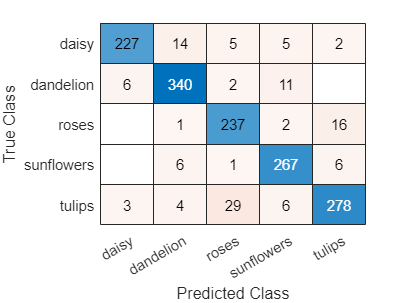

confusionchart(testImgs.Labels,testpreds);